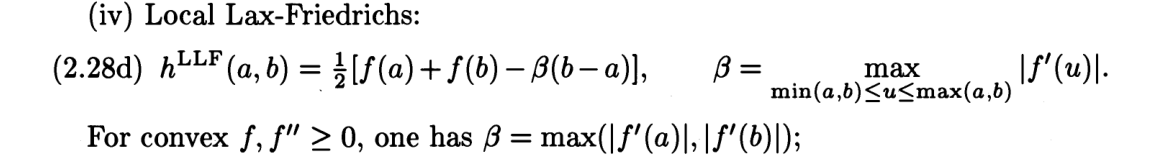

function m_Hflux = Getflux(Upm)
Num = size(Upm,1);
m_Hflux = zeros(Num,1);

LLFflux = @(a,b) 0.5 * ( fu(a) + fu(b) - max(abs(a),abs(b)) * (b - a) );    % 数值通量公式

for i = 2:Num
    m_Hflux(i) = LLFflux(Upm(i-1,2),Upm(i,1));
end

end
